## Identifying a model for the AC generator

## Generate input data

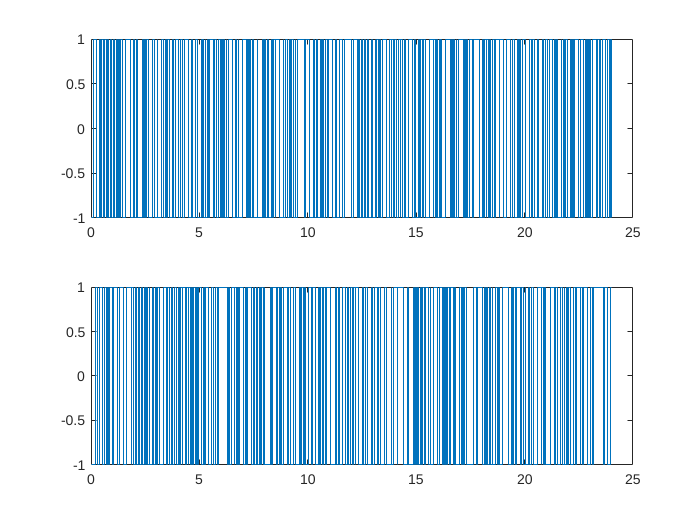


h = 0.02; % Sampling period
N = 1200; % Number of samples

Tfinal = N*h; % The simulation should run this long   
rng(1234); % Change the seed (the argument) to whatever you like
inputMagnitude = 1; % The magnitude of the rbs signal.
uu = inputMagnitude*idinput(2*N, 'rbs', [0, 0.4]); % This generates the random binary sequence 

% Split the rbs signal in two
u1 = uu(1:N);
u1v = uu(N+1:end);
t = (1:N)'*h;
input1 = cat(2, t, u1);
input1v = cat(2, t, u1v);

figure(1)
subplot(211)
stairs(input1(:,1), input1(:,2))
subplot(212)
stairs(input1v(:,1), input1v(:,2))

### Run simulation

% Run script to make sure parameters for the AC generator are set
ac_generator_parameters();

K_gen = 5.3052e+03

f_gen = 4.2217

out = sim('ac_generator_sysid', Tfinal) 

out =   Simulink.SimulationOutput:

                 simout: [1x1 timeseries] 
                   tout: [24001x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


## Load data

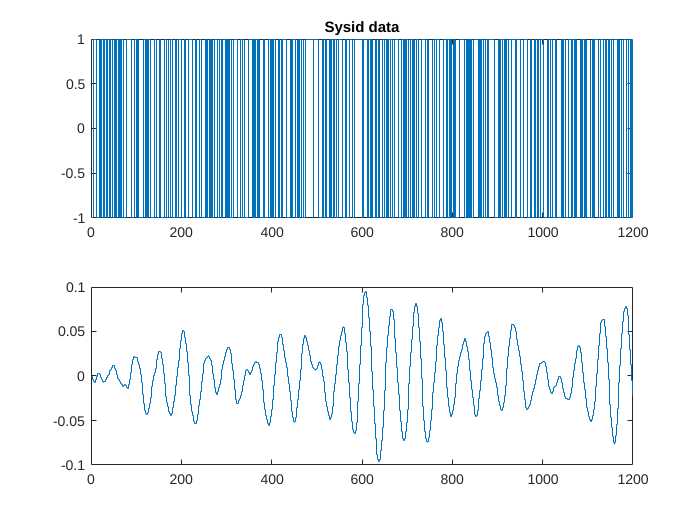

uident = out.simout.Data(3:end,1);
yident = out.simout.Data(3:end,2);
uval = out.simout.Data(3:end,3);
yval = out.simout.Data(3:end,4);

figure()
subplot(211);
stairs(uident)
title('Sysid data')
subplot(212)
stairs(yident)

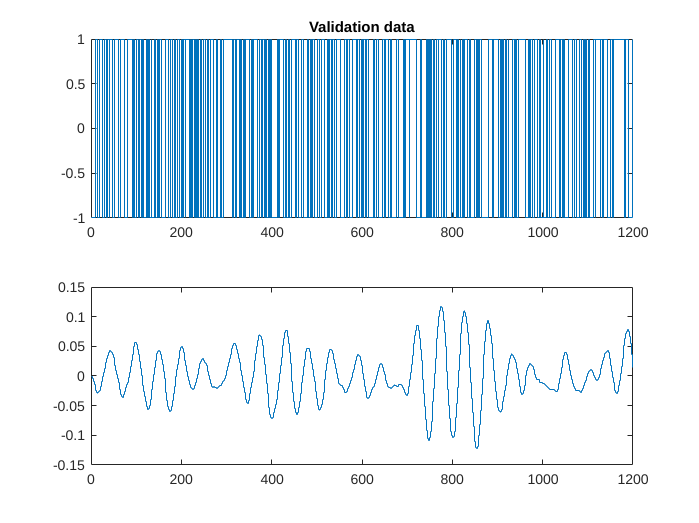


figure()
subplot(211);
stairs(uval)
title('Validation data')
subplot(212)
stairs(yval)

## Estimate models

iddta1 = iddata(yident,uident, h);
valdta1 = iddata(yval, uval, h);

% Second order model, one zero, two poles, one delay
% (b0 z + b1) / (z^2 + a1z + a2)
arx221 = arx(iddta1, [2, 2, 1])

arx221 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 1.984 z^-1 + 0.9981 z^-2              
                                                   
  B(z) = 0.0002131 z^-1 + 0.0002 z^-2              
                                                   
Sample time: 0.02 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=2   nk=1
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 99.61% (prediction focus)
FPE: 2.009e-08, MSE: 1.989e-08                   
 
Model Properties



% Second order model, one zero, two poles, two delays
% (b0 z + b1) /(z*(z^2 + a1z + a2))
arx222 = arx(iddta1, [2, 2, 2])

arx222 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 1.982 z^-1 + 0.996 z^-2               
                                                   
  B(z) = 0.000339 z^-2 - 4.389e-05 z^-3            
                                                   
Sample time: 0.02 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=2   nk=2
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 99.38% (prediction focus)
FPE: 5.098e-08, MSE: 5.047e-08                   
 
Model Properties



% fourth order model, three zeros, four poles, one delay
% (b0 z^3 + b1z^2 + b2z + b3) / (z^4 + a1z^3 + a2z^2 + a3z + a4)
arx441 = arx(iddta1, [4, 4, 1])

arx441 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                       
  A(z) = 1 - 2.604 z^-1 + 2.597 z^-2 - 1.351 z^-3 + 0.368 z^-4            
                                                                          
  B(z) = 0.0002144 z^-1 + 6.817e-05 z^-2 - 4.883e-05 z^-3 + 7.512e-05 z^-4
                                                                          
Sample time: 0.02 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=4   nk=1
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 99.68% (prediction focus)
FPE: 1.393e-08, MSE: 1.365e-08                   
 



% sixth order model, five zeros, six poles, one delay
arx661 = arx(iddta1, [6, 6, 1])

arx661 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                         
  A(z) = 1 - 2.715 z^-1 + 3.038 z^-2 - 2.234 z^-3 + 1.454 z^-4 - 0.7341 z^-5 + 0.201 z^-6                   
                                                                                                            
  B(z) = 0.0002151 z^-1 + 4.306e-05 z^-2 - 2.241e-05 z^-3 + 4.788e-05 z^-4 - 2.647e-05 z^-5 + 4.361e-05 z^-6
                                                                                                            
Sample time: 0.02 seconds
  
Parameterization:
   Polynomial orders:   na=6   nb=6   nk=1
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 99.69% (prediction focus)
FPE: 1.295e-08, MSE: 1.257e-08                   
 



% sixth order model, five zeros, six poles, two delays
arx662 = arx(iddta1, [6, 6, 2])

arx662 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                         
  A(z) = 1 - 2.671 z^-1 + 2.899 z^-2 - 2.046 z^-3 + 1.294 z^-4 - 0.6439 z^-5 + 0.1772 z^-6                  
                                                                                                            
  B(z) = 0.0001891 z^-2 - 4.924e-05 z^-3 + 2.035e-05 z^-4 - 3.319e-05 z^-5 + 7.594e-05 z^-6 - 2.579e-05 z^-7
                                                                                                            
Sample time: 0.02 seconds
  
Parameterization:
   Polynomial orders:   na=6   nb=6   nk=2
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 99.43% (prediction focus)
FPE: 4.398e-08, MSE: 4.268e-08                   
 



% eigth order model, seven zeros, eight poles, one delay
arx881 = arx(iddta1, [8, 8, 1])

arx881 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                                
  A(z) = 1 - 2.767 z^-1 + 3.239 z^-2 - 2.63 z^-3 + 2.058 z^-4 - 1.557 z^-5 + 1.072 z^-6 - 0.5457 z^-7 + 0.1421 z^-8
                                                                                                                   
                                                                                                                   
  B(z) = 0.0002135 z^-1 + 3.274e-05 z^-2 - 1.111e-05 z^-3 + 3.35e-05 z^-4 - 1.278e-05 z^-5 + 2.981e-05 z^-6        
                                                                                  - 2.377e-05 z^-7 + 2.675e-05 z^-8
                                                                                                                   
Sample time: 0.02 seconds
  
Parameterization:
   Polynomial orders:   na=8   nb=8   nk=1
   Number of free coefficients: 16
   Use "polydata", "getpvec", "getcov" for parameters 



% Fourth order state space model
ss4 = n4sid(iddta1, 4);

% Sixth order state space model
ss6 = n4sid(iddta1, 6);


## Compare models

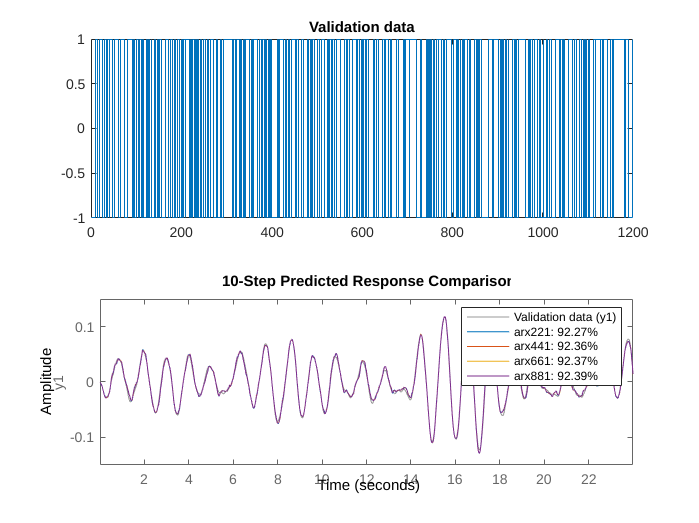

compare(valdta1, arx221, arx441, arx661, arx881, 10)

aic(arx221, arx441, arx661, arx881)

Model quality according to the "nAIC" measure:
  -17.7229  -18.0893  -18.1618  -18.1993



## Export models for use in Simulink

[num, den] = tfdata(tf(arx221))

num = 1×1 cell array
    {[0 2.1309e-04 2.0003e-04]}


den = 1×1 cell array
    {[1 -1.9839 0.9981]}


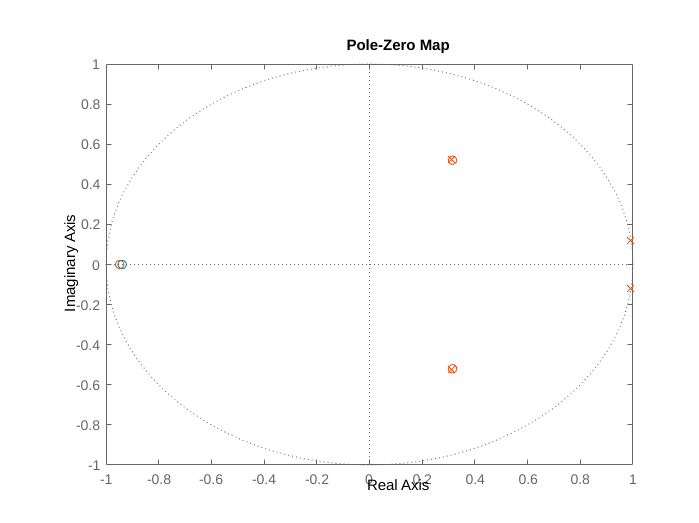

figure()
clf
pzmap(arx221, arx441)

save ac_generator_sysid_result.mat arx221 arx441
